clear all
close all
clc

load intrinsic.mat;
Kc = cameraParams4.Intrinsics.IntrinsicMatrix';
D = cat(2,cameraParams4.Intrinsics.RadialDistortion, cameraParams4.Intrinsics.TangentialDistortion);
load light_plane_undistort.mat;
nl_u = nl;
d_u = d;
load light_plane.mat;

% test_imageFile = 'D:\Projects\LineStructureLightCalib\data\needlepoint\20-1.bmp';
% test_imageFile = 'D:\Projects\LineStructureLightCalib\data\needlepoint\20-2.bmp';
test_imageFile = 'D:\Projects\LineStructureLightCalib\data\needlepoint\40-1.bmp';
% test_imageFile = 'D:\Projects\LineStructureLightCalib\data\needlepoint\60-1.bmp';

I = imread(test_imageFile);

if length(size(I))==3 
    im = rgb2gray(I);
    im = im2single(im);
else
    im = im2single(I);
end
im0=im;

1、在原图上获取光斑中心

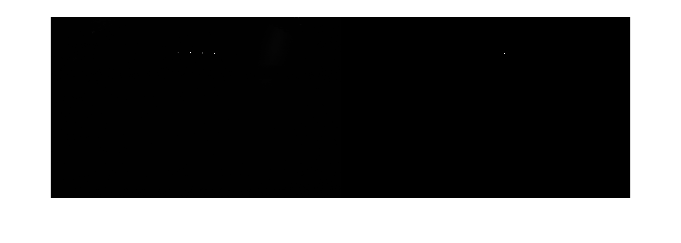

level = 0.3;
mask = im > level;
f1 =  figure('Name', 'Needle Light Spot and mask');
imshowpair(im, mask, 'montage');

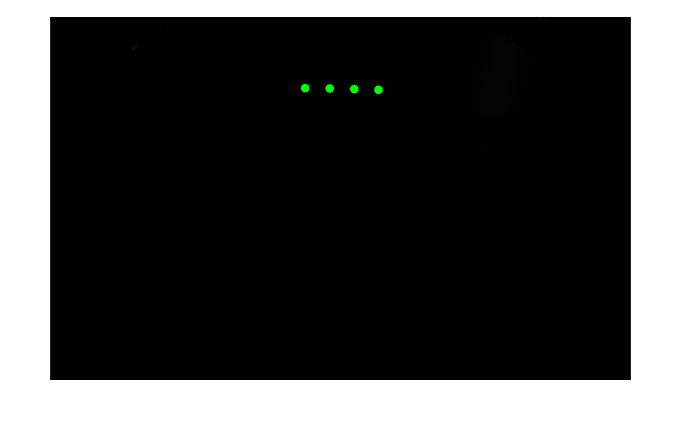

% 光斑中心定位
% 高斯拟合法
% coor1 = gausscenter(im,mask); 
% 重心法
coor2 = gravitycenter(im,mask);
% 中心法
% coor3 = geometriccenter(mask);
f2 =  figure('Name', 'Needle Light Spot Center');
imshow(im),hold on
% plot(coor1(:,2),coor1(:,1),'r+','MarkerSize',15) % 高斯法
plot(coor2(:,2),coor2(:,1),'g.','MarkerSize',15) % 重心法

% plot(coor3(:,2),coor3(:,1),'bo','MarkerSize',15) % 中心法
% legend({'高斯法','重心法','中心法'})

2、分别获取光斑中心和矫正图像的光斑中心

%采用重心法作为光斑的中心点，
spot_centers = coor2(:,[2,1]); % 坐标[x,y]
% 畸变矫正
% spot_centers_u = undistortPoints_my(spot_centers, Kc, D);
spot_centers_u = undistortPoints(spot_centers,cameraParams4);

3、选取测量光斑点对

i=1;
j=2;

4、不利用畸变矫正测量结果

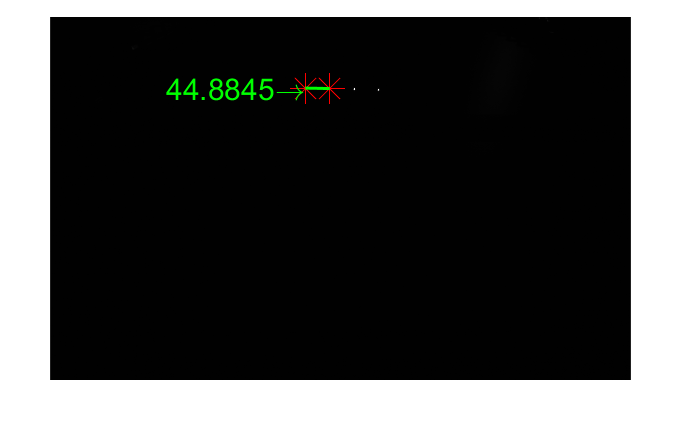

% 计算每一个光斑点的相机世界坐标
[coors_camera] = get_points_camera_coord(spot_centers, Kc, nl, d);
p1 = coors_camera(i,:);
p2 = coors_camera(j,:);
dist = norm(p1-p2);
f3 = figure('Name','Show the distance of two points');
title('result without undistortion')
imshow(im);
hold on;
plot(spot_centers(i,1),spot_centers(i,2),'r*', 'MarkerSize', 15);
hold on;
plot(spot_centers(j,1),spot_centers(j,2),'r*', 'MarkerSize', 15);
hold on;
plot([spot_centers(i,1), spot_centers(j,1)], [spot_centers(i,2), spot_centers(j,2)], 'Color','green','LineWidth',1.5);
hold on;
text(spot_centers(i,1), spot_centers(i,2), strcat(num2str(dist),'\rightarrow'), 'HorizontalAlignment', 'right', 'FontSize',15, 'Color', 'green');

5、利用畸变矫正测量结果

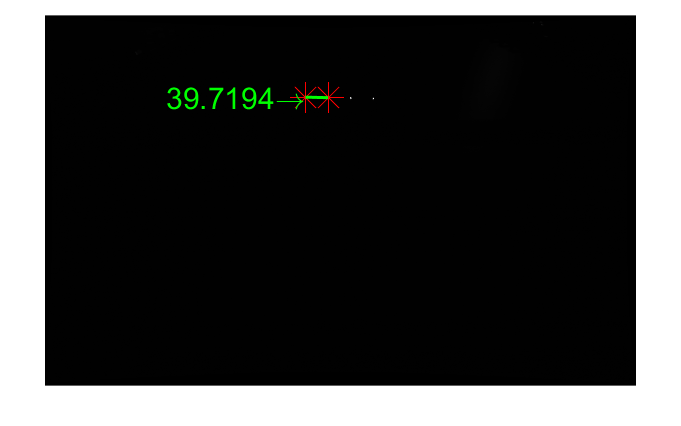

[coors_camera_u] = get_points_camera_coord(spot_centers_u, Kc, nl_u, d_u);
p1_u = coors_camera_u(i,:);
p2_u = coors_camera_u(j,:);
dist_u = norm(p1_u-p2_u);
f4 = figure('Name','Show the distance of two points in undistorted image');
title('result with undistortion')
[im_u,im_u_newOrigin] = undistortImage(im,cameraParams4,'OutputView','full');
imshow(im_u);
hold on;
plot(spot_centers_u(i,1)-im_u_newOrigin(1),spot_centers_u(i,2)-im_u_newOrigin(2),'r*', 'MarkerSize', 15);
hold on;
plot(spot_centers_u(j,1)-im_u_newOrigin(1),spot_centers_u(j,2)-im_u_newOrigin(2),'r*', 'MarkerSize', 15);
hold on;
plot([spot_centers_u(i,1), spot_centers_u(j,1)]-im_u_newOrigin(1), [spot_centers_u(i,2), spot_centers_u(j,2)]-im_u_newOrigin(2), 'Color','green','LineWidth',1.5);
hold on;
text(spot_centers_u(i,1)-im_u_newOrigin(1), spot_centers_u(i,2)-im_u_newOrigin(2), strcat(num2str(dist_u),'\rightarrow'), 'HorizontalAlignment', 'right', 'FontSize',15, 'Color', 'green');